## Reading global specs file

filename = 'global_specs.txt';
params = ReadFile(filename);

Non-comment lines:
    {'wav'}    {'animal_call.wav'}    {'10000'}    {'tone'}    {'10000'}    {'4'}    {'0.5'}    {'2500, 200, 300, 400'}    {'1'}    {'rect'}    {'50'}    {'fir'}    {'10'}    {'butterworth'}    {'bp'}    {'1000, 4000'}    {'0.05'}    {'1'}    {'lin'}    {'log'}    {'nyquist'}    {'20'}

Chosen signal:
wav
Filename:
animal_call.wav
Target sampling frequency:
       10000

Generated signal type:
tone
Generator sampling frequency:
       10000

Generated signal duration:
     4

Spectral resolution:
     1

Window type:
rect
Overlap:
    50

Filtering method:
fir
Filter order:
    10

Approximation method:
butterworth
Filter type:
bp
Cut-off frequencies:
        1000        4000

X-axis time limit:
    0.0500

Y-axis amplitude limit:
     1

X-axis scaling:
lin
Y-axis scaling:
log
X-axis frequency limit:
        5000

Y-axis spectral amplitude limit:
    20



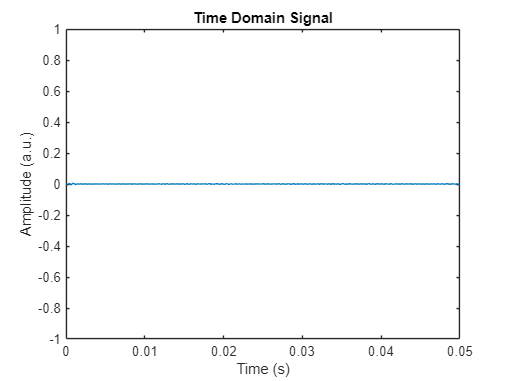

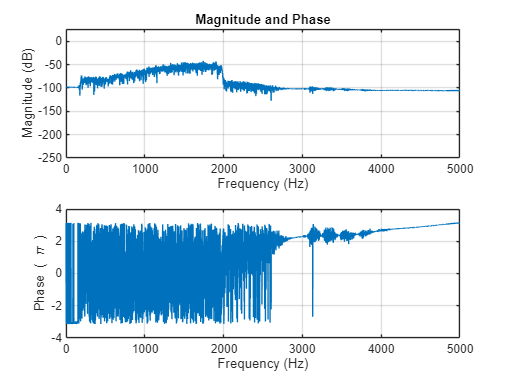

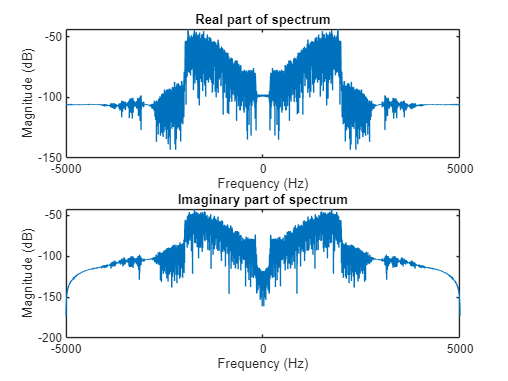

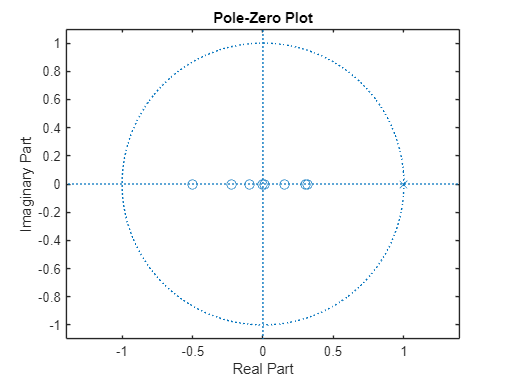

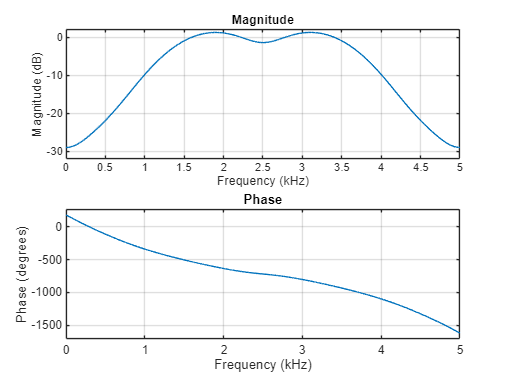

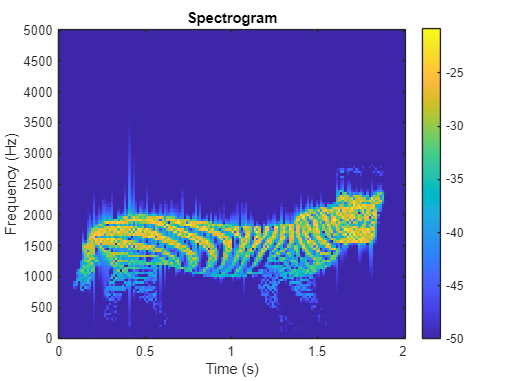

if strcmp(params.chosen_signal,'generate')
    [signal,t]=generate_signal1(params);
    Fs=params.generator_fs;
    audiowrite("inputsignal_generated.wav", signal, Fs);
end
if strcmp(params.chosen_signal,'wav')
    filePath = params.filename;
    [signal, Fs] = audioread(filePath);
    signal=resample(signal,params.target_fs,Fs);
    Fs=params.target_fs;
    t=0:1/Fs:length(signal)*(1/Fs)-(1/Fs);
end
[B, A] = design_filter(params, 0.5);
signal = filter(B, A, signal);
audiowrite("outputsignal.wav", signal, Fs);
[DFT_Y, DFT_f, STFT_Y, STFT_f, STFT_t]=frequency_analyser(signal, params, 39, Fs, -100);
plotting(signal, t, B, A, DFT_Y, DFT_f, STFT_Y, STFT_t, STFT_f, params, Fs)


% Save numerator coefficients
save('numerator_coefficients.txt', 'B', '-ascii');

% Save denominator coefficients
save('denominator_coefficients.txt', 'A', '-ascii');

## Storing data as ASCII and plots as pdf

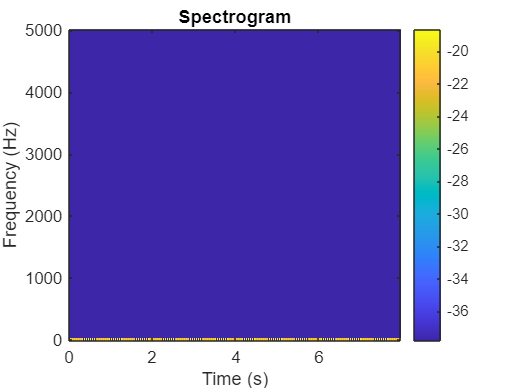

% Example: Filter Coefficients
b = B;  % Example filter coefficients (numerator)
a = A;                   % Example filter coefficients (denominator)

% Save numerator coefficients
save('numerator_coefficients.txt', 'b', '-ascii');

% Save denominator coefficients
save('denominator_coefficients.txt', 'a', '-ascii');

% Save as a PDF with minimal white space
exportgraphics(gcf, 'filter_response.pdf', 'ContentType', 'vector', 'BackgroundColor', 'none');